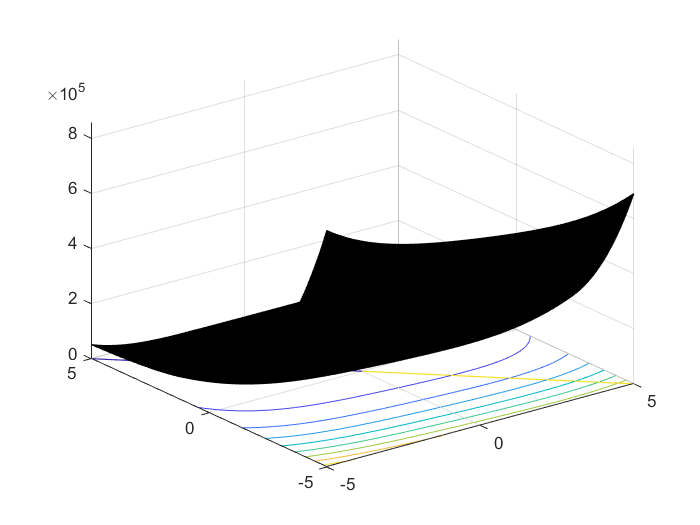

x = (-5:0.01:5);
y= (-5:0.01:5);
[X,Y] = meshgrid(x,y);
f = penaltyF(X,Y);
surfc(X,Y,f)

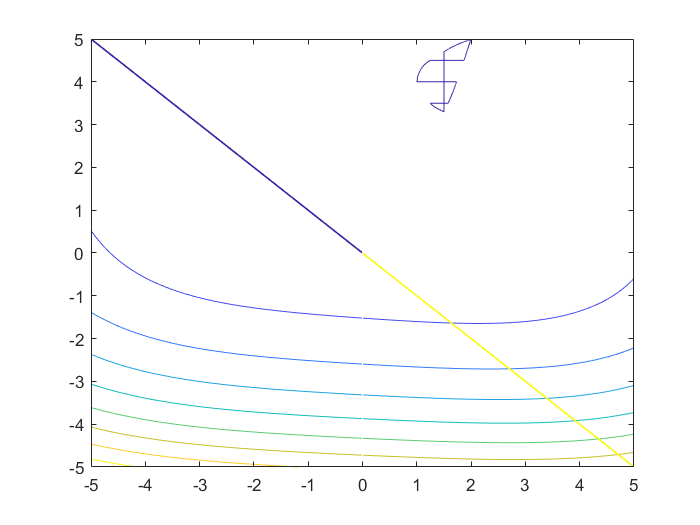

contour(X,Y,f)

options = optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj','on','MaxIter',1000);
[opt,optval] = fminunc(@(t)costFunction(t),[10,10]',options)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


opt =     1.0015
    3.9575


optval = 7.4002e-06

function value = penaltyF(x,y)
value = zeros(length(x),1);
f = @(x,y) -(sin(2*pi.*x).^3.*sin(2*pi*y)./(x.^3.*(x+y)));
gtr1 = @(x,y) (x-0);
gtr2 = @(x,y) (y-0);

lwr1 = @(x,y) x.^2-y+1;
lwr2 = @(x,y) 1-x+(y-4).^2;
lwr3 = @(x,y) (x-10);
lwr4 = @(x,y) (y-10);
R = 100;

violation1 = gtr1(x,y)<0;
violation2 = gtr2(x,y)<0;

violation3 = lwr1(x,y)>0;
violation4 = lwr2(x,y)>0;
violation5 = lwr3(x,y)>0;
violation6 = lwr4(x,y)>0;

value = value +f(x,y) +R.*(violation1.*gtr1(x,y).^2+violation2.*gtr2(x,y).^2+violation3.*lwr1(x,y).^2+violation4.*lwr2(x,y).^2+violation5.*lwr3(x,y).^2+violation6.*lwr4(x,y).^2);

end

function [value,gradient] = costFunction(x)
delta = 10^-4;
value = penaltyF(x(1),x(2));
gradient = zeros(2,1);
gradient(1) = (penaltyF(x(1)+delta,x(2))-penaltyF(x(1)-delta,x(2)))/(2*delta);
gradient(2) = (penaltyF(x(1),x(2)+delta)-penaltyF(x(1),x(2)-delta))/(2*delta);
end